opts = detectImportOptions('fxdata.csv')

opts =   DelimitedTextImportOptions with properties:

   Format Properties:
                    Delimiter: {','}
                   Whitespace: '\b\t '
                   LineEnding: {'\n'  '\r'  '\r\n'}
                 CommentStyle: {}
    ConsecutiveDelimitersRule: 'split'
        LeadingDelimitersRule: 'keep'
       TrailingDelimitersRule: 'ignore'
                EmptyLineRule: 'skip'
                     Encoding: 'UTF-8'

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'
             ExtraColumnsRule: 'addvars'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'YYYY_MM_DD', 'x2019_12_30', 'x2019_12_31' ... and 375 more}
                VariableTypes: {'char', 'double', 'double' ... and 375 more}
    

T = readtable('fxdata.csv',opts)

T = 58×378 table
    YYYY_MM_DD     x2019_12_30    x2019_12_31    x2020_01_02    x2020_01_03    x2020_01_06    x2020_01_07    x2020_01_08    x2020_01_09    x2020_01_10    x2020_01_13    x2020_01_14    x2020_01_15    x2020_01_16    x2020_01_17    x2020_01_20    x2020_01_21    x2020_01_22    x2020_01_23    x2020_01_24    x2020_01_27    x2020_01_28    x2020_01_29    x2020_01_30    x2020_01_31    x2020_02_03    x2020_02_04    x2020_02_05    x2020_02_06    x2020_02_07    x2020_02_10

X = T;
Xc = table2cell(X);
X_transposed = Xc';

A = X_transposed;
tickers = A(1,:);
data = A(2:378,:);

data = cell2mat(data);

data = fillmissing(data, "previous",1);

daily_returns = zeros(376, 58); % Initialization

% Compute the daily returns
for j =1:58
    for i=1:376
        daily_returns(i,j) = (data(i+1,j) - data(i,j)) / data(i,j);
    end
end

% Compute the correlation matrix of daily returns
correlation = corrcoef(daily_returns);

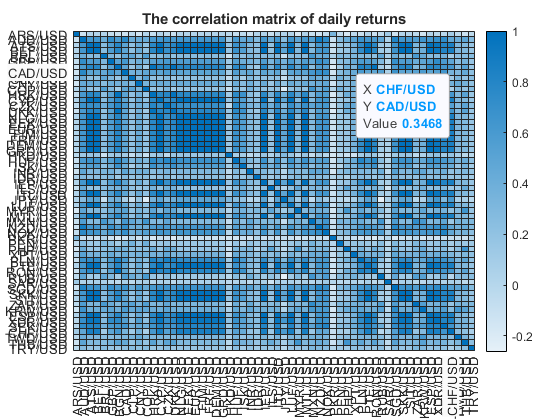

figure;
h = heatmap(correlation);
h.XDisplayLabels = string(tickers);
h.YDisplayLabels = string(tickers);
title("The correlation matrix of daily returns");

[temp, order] = sort(correlation(1,:));
answer = correlation(:,order);
[temp, order] = sort(answer(:,1));
answer2 = answer(:,order);

MeanCorrMatPerm=mean(correlation);

'clustergram' requires Bioinformatics Toolbox.

[sortedCorr, indPerm]=sort(MeanCorrMatPerm,'descend');
sorted = correlation(indPerm,indPerm);
sort_title= tickers(:,indPerm );

figure;
h = heatmap(sorted,"Colormap",turbo);
h.XDisplayLabels = string(sort_title);
h.YDisplayLabels = string(sort_title);
title("The correlation matrix of daily returns");

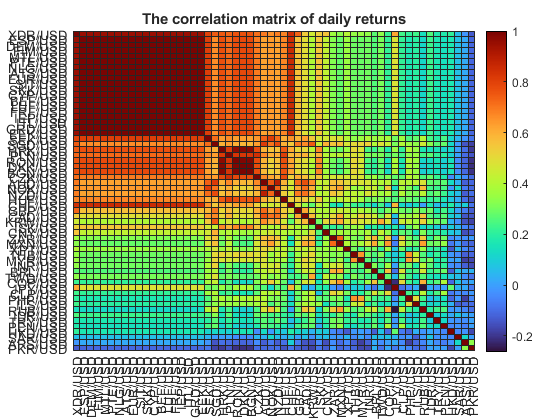

x = string(zeros(58*58, 1));
y = string(zeros(58*58, 1));
value = zeros(58*58, 1);

index = 1;
for i=1:58
    for j = 1:58        
        x(index) = erase(sort_title(i), '/USD');
        y(index) = erase(sort_title(j), '/USD');
        value(index) = sorted(i,j);  
        index = index + 1;
    end
end

T1 = array2table(x,'VariableNames',{'x'});
T1.y = y;
T1.value = value;

writetable(T1,'myData.csv','Delimiter',',')  